# Contest Report

% Read in the list of all solvers
solvers = readtimetable("allSolvers.csv");

% Get rid of bad entries
% The score may be infinite or negative. Neither is a good state.
ix = isinf(solvers.score)|(solvers.result<0);
solvers(ix,:) = [];

Here is the list of all the solvers

solvers


solvers =

  0x5 empty timetable

    t    result    computeTime    score    author    commit
    _    ______    ___________    _____    ______    ______




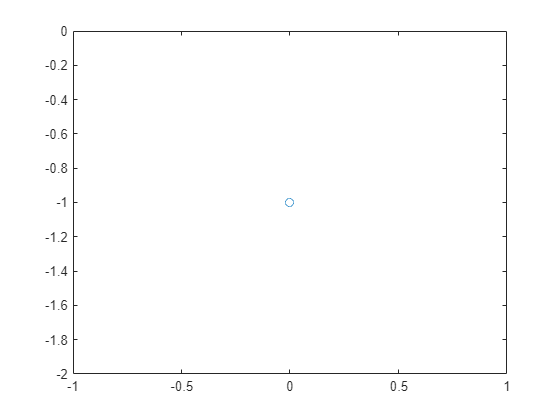

plot(solvers.computeTime,solvers.result,"-o")

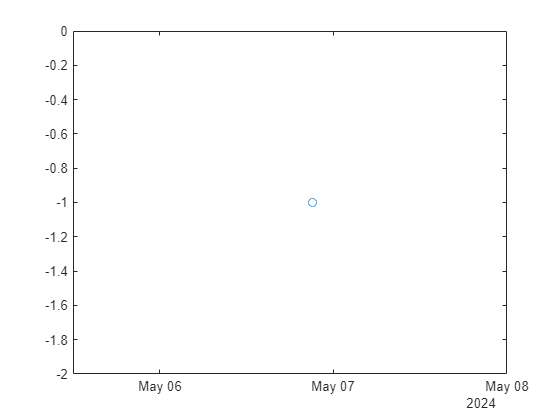

plot(solvers.t,solvers.result,"-o")